%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 《控制之美-卷二》 代码

## 作者：王天威，黄军魁

## 清华大学出版社

## 程序名称：LQR_Test_tracking_Delta_U_MSD

## 程序功能：弹簧质量阻尼系统 -输入增量非常数目标（4.5.4节案例）

## 所用模块：

## [F1]反馈矩阵求解模块

## [F3]输入增量控制矩阵转换模块

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 程序初始化，清空工作空间，缓存，

clear all;
close all;
clc;

## 定义系统参数

定义质量块质量

m_sys = 1;
% 定义阻尼系数
b_sys = 0.5;
% 定义弹簧弹性系数
k_sys = 1;

%%%%%%%%%%%%%%%%%系统定义%%%%%%%%%%%%%%%%%%%%%
% 构建系统矩阵A，n x n
A = [0 1 ; -k_sys/m_sys -b_sys/m_sys]

A =          0    1.0000
   -1.0000   -0.5000


% 计算A矩阵维度
n = size (A,1);
% 构建输入矩阵B，n x p
B = [0; 1/m_sys]

B =      0
     1


C=[1 0;0 1]

C =      1     0
     0     1


D=[0;0]

D =      0
     0


% 计算输入矩阵维度
p = size(B,2);

%%%%%%%%%%%%%%%%%%系统离散%%%%%%%%%%%%%%%%%%%%
% 离散时间步长
Ts = 0.1;
% 连续系统转离散系统
sys_d = c2d(ss(A,B,C,D),Ts);
% 提取离散系统A矩阵
A = sys_d.a

A =     0.9951    0.0974
   -0.0974    0.9464


% 提取离散系统B矩阵
B = sys_d.b

B =     0.0049
    0.0974



%%%%%%%%%%%%%%%%%权重设计%%%%%%%%%%%%%%%%%%%%%
% 设计状态权重系数矩阵, n x n
Q = [1 0 ; 0 1];
% 设计终值权重系数矩阵, n x n
S = [1 0; 0 1];
% 设计输入权重系数矩阵, p x p
R = 1;

%%%%%%%%%%%%%%%%%系统参考值%%%%%%%%%%%%%%%%%%%%
% 系统状态参考值
xd = [0 ; 0.2];
% 构建目标转移矩阵
AD = c2d(ss( [0 1; 0 0],[0;0],C,D),0.1).A

AD =     1.0000    0.1000
         0    1.0000



%%%%%%%%%%%%%%%%%系统初始化%%%%%%%%%%%%%%%%%%%%
% 初始化系统状态
x0 = [0; 0];
% 初始化状态赋值
x = x0;
% 系统输入初始化
u0 = 0;
% 初始输入赋值
u = u0;
% 构建初始化增广状态矩阵，参考式（4.5.23）
xa = [x; xd; u]

xa =          0
         0
         0
    0.2000
         0



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 定义系统运行步数
k_steps = 200;
% 定义x_history零矩阵，用于储存系统状态结果，维度n x k_steps
x_history = zeros(n,k_steps);
% 定义u_history零矩阵，用于储存系统输入结果，维度p x k_steps
u_history = zeros(p,k_steps);
% 定义xd_history零矩阵，用于储存系统目标状态，维度n x k_steps
xd_history = zeros(n,k_steps);

% 调用模块[F3]，计算Aa，Ba，Qa，Sa，和R
[Aa,Ba,Qa,Sa,R] = F3_InputAugmentMatrix_Delta_U(A,B,Q,R,S,AD);
% 调用模块[F1]，计算系统反馈增益，F
[F] = F1_LQR_Gain(Aa,Ba,Qa,R,Sa);

No. of Interation is 34 


Aa

Aa =     0.9951    0.0974         0         0    0.0049
   -0.0974    0.9464         0         0    0.0974
         0         0    1.0000    0.1000         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000


Ba

Ba =     0.0049
    0.0974
         0
         0
    1.0000


Qa

Qa =      1     0    -1     0     0
     0     1     0    -1     0
    -1     0     1     0     0
     0    -1     0     1     0
     0     0     0     0     0


Sa

Sa =      1     0    -1     0     0
     0     1     0    -1     0
    -1     0     1     0     0
     0    -1     0     1     0
     0     0     0     0     0


R

R = 1

% 仿真开始，建立for循环
for k = 1 : k_steps
% 系统目标状态不再是常数，if else语句定义不同阶段的系统目标状态
  if (k==50)
  xd = [xd(1) ; -0.3];%xd(1)不变
  elseif (k==100)
  xd = [xd(1) ; 0.4];
  elseif (k==150)
  xd = [xd(1) ; -0.5];
  elseif (k==200)
  xd = [xd(1) ; 0.1];
  end
% 计算系统输入增量
  Delta_u = -F * xa;
% 计算系统输入
  u = Delta_u + u;
% 系统输入代入系统方程，计算系统响应
  x = A * x + B * u;
% 更新系统增广状态，参考式（4.5.23）
  xd = AD * xd;
  xa = [x; xd; u];
% 保存系统状态到预先定义矩阵的相应位置
  x_history (:,k+1) =  x;
% 保存系统输入到预先定义矩阵的相应位置
  u_history (:,k) = u ;
% 保存系统目标状态到预先定义的矩阵的相应位置
  xd_history (:,k+1) =  xd;
end

%%%%%%%%%%%%%%%%%结果%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(1);
set(gcf, 'Position', [150 150 500 675]);

% 系统状态x1结果图，质量块位移
subplot  (3, 1, 1);
hold;

已锁定最新绘图


plot (0:length(x_history)-1,x_history(1,:),"linewidth",1);
plot (0:length(xd_history)-1,xd_history(1,:),'--',"linewidth",2);
grid on
legend("x1","x1d")
hold off;
xlim([0 k_steps]);
ylim([-0.2 1.2]);

% 系统状态x2结果图，质量块速度
subplot  (3, 1, 2);
hold;

已锁定最新绘图


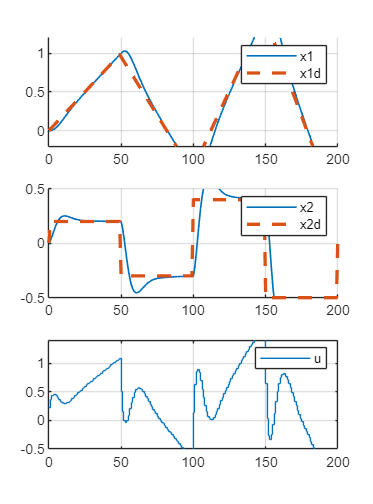

plot (0:length(x_history)-1,x_history(2,:),"linewidth",1);
plot (0:length(xd_history)-1,xd_history(2,:),'--',"linewidth",2);
grid on
legend("x2","x2d")
hold off;
xlim([0 k_steps]);
ylim([-0.5 0.5]);

% 系统输入结果图
subplot (3, 1, 3);
stairs (0:length(u_history)-1,u_history(1,:));
legend("u")
grid on
xlim([0 k_steps]);
ylim([-0.5 1.4]);